Demodulation(four_QAM([1 0], 1))

ans =      1     0


Convolution_code([1 1])

ans =      1     1     0     1     0     1     1     1


binVal = de2bi(0:3, 2, 'left-msb')  % path metric 계산을 위한 계산

binVal =      0     0
     0     1
     1     0
     1     1


for i = 1:4
    output0(i,:) = Convolution_code_tail_bit_X(0, binVal(i,1:2))
    output1(i,:) = Convolution_code_tail_bit_X(1, binVal(i,1:2))
end

output0 =      0     0
     1     1
     1     0
     0     1


output1 =      1     1
     0     0
     0     1
     1     0


output0 =      0     0
     1     1
     1     0
     0     1


output1 =      1     1
     0     0
     0     1
     1     0


output0 =      0     0
     1     1
     1     0
     0     1


output1 =      1     1
     0     0
     0     1
     1     0


output0 =      0     0
     1     1
     1     0
     0     1


output1 =      1     1
     0     0
     0     1
     1     0


clc
clear
close
rng('default')
%input = randsrc(1, 200, [0 1])
input =[1 0 1 1 0 0 1 1 1 1]

input =      1     0     1     1     0     0     1     1     1     1


encoded_input = Convolution_code(input);
encoded_input = reshape(encoded_input, 2,[])

encoded_input =      1     1     0     0     0     1     1     0     1     1     0     1
     1     0     0     1     1     1     1     1     0     0     1     1



for i = 1:numel(encoded_input)/2
    modulated_output(1,i)=four_QAM(encoded_input(1:2,i), 128);
end
modulated_output

modulated_output =   -8.0000 - 8.0000i   8.0000 - 8.0000i   8.0000 + 8.0000i  -8.0000 + 8.0000i  -8.0000 + 8.0000i  -8.0000 - 8.0000i  -8.0000 - 8.0000i  -8.0000 + 8.0000i   8.0000 - 8.0000i   8.0000 - 8.0000i  -8.0000 + 8.0000i  -8.0000 - 8.0000i


received_signal = AWGN_Channel(modulated_output,2)

received_signal =   -6.9247 - 6.5492i  11.6678 - 8.1261i   3.4823 + 9.4295i  -6.2757 + 7.5901i  -7.3625 + 7.7517i -10.6154 - 5.0206i  -8.8672 - 5.1819i  -7.3148 +10.8344i  15.1568 - 6.6570i  13.5389 -10.4150i -10.6998 + 9.4345i  -1.9302 - 4.7395i


for i = 1:length(received_signal)
    demodulated_output(1,2*(i-1)+1 : 2*i)=Demodulation(received_signal(1,i));
end
demodulated_output = reshape(demodulated_output, 2, [])

demodulated_output =      1     1     0     0     0     1     1     0     1     1     0     1
     1     0     0     1     1     1     1     1     0     0     1     1


decoding = Viterbi_decoding(demodulated_output, 10)
bit_error = nnz(input-decoding)

% soft decision
clc
clear
close
rng('default')
%input = randsrc(1, 10, [0 1])
%input = [1 0]
input =[1 0 1 1 0 0 1 1 1 1]

input =      1     0     1     1     0     0     1     1     1     1


encoded_input = Convolution_code(input);
encoded_input = reshape(encoded_input, 2, [])

encoded_input =      1     1     0     0     0     1     1     0     1     1     0     1
     1     0     0     1     1     1     1     1     0     0     1     1


E_symbol = 128;
noise_v = 2;
for i = 1:numel(encoded_input)/2
    modulated_output(1,i)=four_QAM(encoded_input(1:2,i), E_symbol);
end
modulated_output

modulated_output =   -8.0000 - 8.0000i   8.0000 - 8.0000i   8.0000 + 8.0000i  -8.0000 + 8.0000i  -8.0000 + 8.0000i  -8.0000 - 8.0000i  -8.0000 - 8.0000i  -8.0000 + 8.0000i   8.0000 - 8.0000i   8.0000 - 8.0000i  -8.0000 + 8.0000i  -8.0000 - 8.0000i


received_signal = AWGN_Channel(modulated_output,noise_v)

received_signal =   -6.9247 - 6.5492i  11.6678 - 8.1261i   3.4823 + 9.4295i  -6.2757 + 7.5901i  -7.3625 + 7.7517i -10.6154 - 5.0206i  -8.8672 - 5.1819i  -7.3148 +10.8344i  15.1568 - 6.6570i  13.5389 -10.4150i -10.6998 + 9.4345i  -1.9302 - 4.7395i


received_signal=[real(received_signal);imag(received_signal)]

received_signal =    -6.9247   11.6678    3.4823   -6.2757   -7.3625  -10.6154   -8.8672   -7.3148   15.1568   13.5389  -10.6998   -1.9302
   -6.5492   -8.1261    9.4295    7.5901    7.7517   -5.0206   -5.1819   10.8344   -6.6570  -10.4150    9.4345   -4.7395


decoding = Viterbi_soft_decoding(received_signal, 10, E_symbol)
bit_error = nnz(input-decoding)

%awgn
clear
close
t = 0:pi/16:2*pi;
x = sqrt(2)*(sin(t)+ 1i *sin(t));
rng('default')
noise_v = 2

noise_v = 2

Esym=sum(abs(x).^2)/(length(x))

Esym = 1.9394

snr = Esym/(2*noise_v^2)

snr = 0.2424

rxSig = awgn(x,10*log10(snr), 'measured')

rxSig =    1.0753 - 1.6190i   3.9437 - 5.6127i  -3.9765 + 3.4180i   2.5100 + 1.4361i   1.6375 - 0.5099i  -1.4395 + 3.9165i   0.4394 - 2.1165i   2.0723 + 1.1826i   8.5710 + 0.9313i   6.9259 + 2.0255i  -1.3932 + 1.9323i   7.2457 - 0.5539i   2.4508 + 0.9399i   0.6596 + 0.4559i   1.9707 + 1.7966i  -0.1340 + 2.4624i  -0.2483 + 2.2185i   2.7035 - 2.0032i   2.2769 - 0.3865i   2.0487 - 3.2139i   0.3430 - 3.2270i  -3.5908 - 1.1896i   0.1279 + 1.7587i   1.8734 - 2.9264i  -0.4364 - 0.6715i   0.6823 - 1.8382i   0.1472 + 0.9281i  -1.7828 - 3.3540i  -0.4123 - 0.9349i  -2.3603 + 0.3194i   1.2356 + 1.6600i  -2.5700 + 2.8125i  -2.1377 + 0.1719i


rng('default')


rxSig3 = AWGN_Channel(x, noise_v)

rxSig3 =    1.0753 - 1.6190i   3.9437 - 5.6127i  -3.9765 + 3.4180i   2.5100 + 1.4361i   1.6375 - 0.5099i  -1.4395 + 3.9165i   0.4394 - 2.1165i   2.0723 + 1.1826i   8.5710 + 0.9313i   6.9259 + 2.0255i  -1.3932 + 1.9323i   7.2457 - 0.5539i   2.4508 + 0.9399i   0.6596 + 0.4559i   1.9707 + 1.7966i  -0.1340 + 2.4624i  -0.2483 + 2.2185i   2.7035 - 2.0032i   2.2769 - 0.3865i   2.0487 - 3.2139i   0.3430 - 3.2270i  -3.5908 - 1.1896i   0.1279 + 1.7587i   1.8734 - 2.9264i  -0.4364 - 0.6715i   0.6823 - 1.8382i   0.1472 + 0.9281i  -1.7828 - 3.3540i  -0.4123 - 0.9349i  -2.3603 + 0.3194i   1.2356 + 1.6600i  -2.5700 + 2.8125i  -2.1377 + 0.1719i


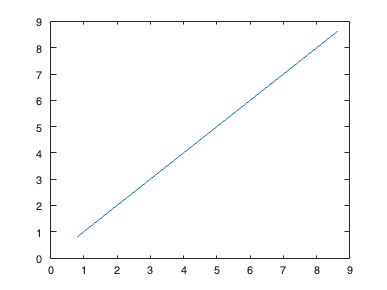

axis([0 9 0 9])
xticks(0:1:9)

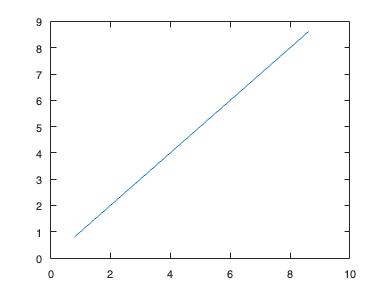

figure; plot(abs(rxSig),abs(rxSig3));

% 4qam test
clc
close
clear
ber = zeros(25,1);
Eb_No_db_sim = 1:25;
N_symbol = 1000000

N_symbol = 1000000

sigma_v = 4;
parfor i = Eb_No_db_sim
    for j = 1:N_symbol
        a = randi([0 1], [1 2]);
        b = four_QAM(a, 2*(10^(i/10))*2*sigma_v^2);
        c = AWGN_Channel(b, sigma_v);
        d = Demodulation(c);
        k = nnz(a-d);
        ber(i, 1) = ber(i, 1) + k;
    end
end
ber = ber / (N_symbol*2);

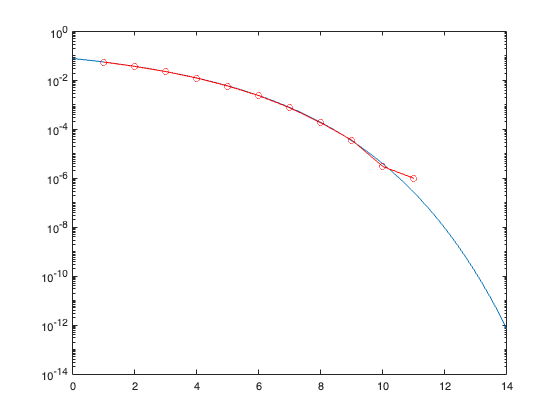


eb_no_db = 0:0.1:14;
semilogy(eb_no_db, qfunc(sqrt(2*10.^(eb_no_db/10))))
hold on
plot(Eb_No_db_sim, ber, 'ro-')

a =1;
b =2;
c =3;
d = a + b + c;
e = a - b - c

e = -4

a * b * c

ans = 6

a / b / c;